# `بسم الله الرحمن الرحيم`

# `Trial for monovslam object using mobile streamed snaps.`

`This live script is used to test out and get familiar with monovslam object using mbile streamed camera snaps.`

m = mobiledev

m.SampleRate = 100;
m.AccelerationSensorEnabled = 1;
m.AngularVelocitySensorEnabled = 1;
m.Logging = 1;
start_time = datetime('now', 'Format', 'yyyy-MM-dd HH:mm:ss');  % Assuming you know the start time
cam = camera(m,'back');

numFrames = 30;
imgs = cell(1, numFrames);
tImgs = datetime.empty(numFrames, 0);
pause(5);
for i = 1:numFrames
    [imgs{i}, tImgs(i)] = snapshot(cam, 'immediate');
    pause(0.1);
    disp(i);
end
[accel, tA] = accellog(m);
[av, tAV] = angvellog(m);
absATstamps = start_time + seconds(tA);
absAVTstamps = start_time + seconds(tAV);

m.Logging = 0;
cam = [];

`If needed to store images in a local directory.`

save('VSLAM_Variables3.mat');

n = numel(imgs);  % Get the number of images in the cell array

for i = 1:n
    img = imgs{i};  % Extract each image from the cell array
    filename = sprintf('image_%d.png', i);  % Create a filename
    imwrite(img, filename);  % Save the image to the current directory
end

`Load mobile camera and IMU parameters.`

load("/home/hazem/Robust-VSLAM-Using-Matlab-Mobile-Streaming/mobile_camera_params.mat");
intrinsics = cameraParams.Intrinsics;
load("/home/hazem/Robust-VSLAM-Using-Matlab-Mobile-Streaming/imu_params.mat");
imuParameters = imuParams;

`Create VSLAM object.`

myVslam = monovslam(intrinsics, imuParameters, "TrackFeatureRange", [40 400])

myVslam =   monovslam with properties:

              Intrinsics: [1×1 cameraIntrinsics]
           IMUParameters: [1×1 factorIMUParameters]
             ScaleFactor: 1.2000
               NumLevels: 8
            MaxNumPoints: 1000
           SkipMaxFrames: 20
       TrackFeatureRange: [40 400]
    LoopClosureThreshold: 60
     CustomBagOfFeatures: []
                 Verbose: 0
    CameraToIMUTransform: [1×1 rigidtform3d]
       AlignmentFraction: 0.9000
       MaxAlignmentError: 1
       NumPosesThreshold: 40
           VocabFilePath: '/usr/local/MATLAB/R2024b/toolbox/vision/builtins/src/shared/vslamcore/bagOfFeatures.bin.gz'
            IsIMUAligned: 0
         GravityRotation: []
                IMUScale: 1


    FrequentKeyFrames

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful

    TrackingSuccessful



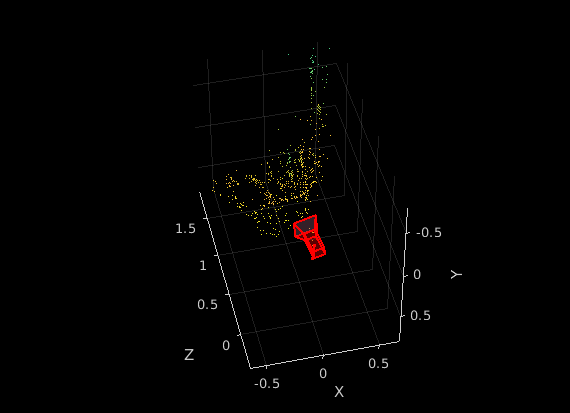

keyFramesNum = 0;
imageCurrent = undistortImage(imgs{1},intrinsics);
addFrame(myVslam,imageCurrent);
for i = 2:numFrames
    imageCurrent = rgb2gray(undistortImage(imgs{i},intrinsics));
    startTime = tImgs(i-1);
    endTime = tImgs(i);
    accelInRange = accel((absATstamps >= startTime) & (absATstamps <= endTime), :);
    avInRange = av((absAVTstamps >= startTime) & (absAVTstamps <= endTime), :);
    minlength = min(length(accelInRange), length(avInRange));
    accelInRange = accelInRange(1:minlength,:);
    avInRange = avInRange(1:minlength,:);
    addFrame(myVslam,imageCurrent, avInRange, accelInRange)
    %addFrame(myVslam,imageCurrent)

    %%Get current status of system
    status = checkStatus(myVslam);
    disp(status);

    if hasNewKeyFrame(myVslam)
        keyFramesNum = keyFramesNum +1;
    end
    % Display 3-D map points and camera trajectory
    plot(myVslam);



end 

xyzPoints = mapPoints(myVslam);
camPoses = poses(myVslam);

Extras to visualize certain image and its features.

grayImage = rgb2gray(imgs{1}); % Convert to grayscale if it's a color image
imshow(grayImage);
title('Input Image');

% Detect ORB features
orbPoints = detectORBFeatures(grayImage);

% Plot the features
imshow(grayImage);
hold on;
plot(orbPoints.selectStrongest(50)); % Display the strongest 50 features
title('ORB Features');
hold off;

[features, validPoints] = extractFeatures(grayImage, orbPoints);